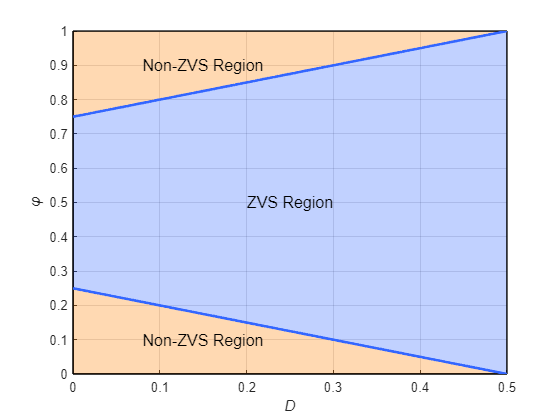

% 定义范围 
D = linspace(0, 0.5, 500);  % D 从 0 到 0.5 的范围，取 500 个点
phi = linspace(0, 1, 500);  % phi 从 0 到 1 的范围，取 500 个点

% 计算 phi1 和 phi2 的值
phi1 = -0.5 .* D + 0.25;
phi2 = 0.5 .* D + 0.75;

% 绘制结果
figure;

% 填充 phi1 和 phi2 之间的区域
hold on;
fill([D, fliplr(D)], [phi1, fliplr(phi2)], [0.2, 0.4, 1], 'FaceAlpha', 0.3);  % 填充区域1（橙色）

% 填充剩余空间（两条曲线之外的区域）
fill([0, 0, 0.5], [0, 0.25, 0], [1, 0.5, 0], 'FaceAlpha', 0.3);  % 填充区域2（蓝色）
fill([0, 0, 0.5], [1, 0.75, 1], [1, 0.5, 0], 'FaceAlpha', 0.3);  % 填充区域3（蓝色）

% 绘制 phi1 和 phi2 曲线
plot(D, phi1, 'LineWidth', 2, 'Color', [0.2, 0.4, 1]);  % 绘制 phi1 曲线
plot(D, phi2, 'LineWidth', 2, 'Color', [0.2, 0.4, 1]);  % 绘制 phi2 曲线

% 设置图形属性
xlabel('\it{D}');
ylabel('\it{φ}');
grid on;
hold off;

% 设置ZVS标记
text(0.25, 0.5, 'ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');
text(0.15, 0.1, 'Non-ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');
text(0.15, 0.9, 'Non-ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');